% Author Name: Matthew Burke
% Email: burkem37@rowan.edu
% Course: MATLAB Programming - Fall 2024
% Assignment: Assignment 2
% Task: Population Growth Analysis
% Date: October 19, 2024

% Read stock data from the file
data = load('stock_data.txt');

% Calculate statistics
average_price = mean(data);
highest_price = max(data);
lowest_price = min(data);
days_increase = sum(diff(data) > 0); % Count days where the price increased

% Print the calculated statistics
fprintf('Average Closing Price: %.2f\n', average_price);

Average Closing Price: 10.17


fprintf('Highest Closing Price: %.2f\n', highest_price);

Highest Closing Price: 16.76


fprintf('Lowest Closing Price: %.2f\n', lowest_price);

Lowest Closing Price: 2.19


fprintf('Number of Days Price Increased: %d\n', days_increase);

Number of Days Price Increased: 14



% Create a line plot of daily closing prices
f = figure;
f.Position = [10 10 550 600]

f =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [10 10 550 600]
       Units: 'pixels'

  Show all properties


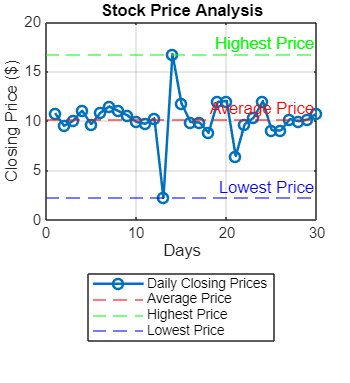

plot(data, '-o', 'DisplayName', 'Daily Closing Prices', 'LineWidth', 1.5);
hold on;
yline(average_price, 'r--', 'Average Price', 'DisplayName', 'Average Price');
yline(highest_price, 'g--', 'Highest Price', 'DisplayName', 'Highest Price');
yline(lowest_price, 'b--', 'Lowest Price', 'DisplayName', 'Lowest Price');
hold off;

% Add labels, title, and legend
xlabel('Days');
ylabel('Closing Price ($)');
title('Stock Price Analysis');
legend('Location', 'southoutside');
grid on;

% Save the plot as an image file
saveas(gcf, 'stock_analysis.png');


% Write a summary of the analysis to a new file
fileID = fopen('stock_summary.txt', 'w');
fprintf(fileID, 'Stock Analysis Summary:\n');
fprintf(fileID, 'Average Closing Price: %.2f\n', average_price);
fprintf(fileID, 'Highest Closing Price: %.2f\n', highest_price);
fprintf(fileID, 'Lowest Closing Price: %.2f\n', lowest_price);
fprintf(fileID, 'Number of Days Price Increased: %d\n', days_increase);
fclose(fileID);

% Display a message indicating completion
disp('Analysis complete and results saved.');

Analysis complete and results saved.
